# Generate noise and calculate Noise Power

Choose Power Parameters

noiseFloorDBMHZ = -30; % dBm/Hz
bandwidth = 1e6; % Hz (-bandwidth/2 -> bandwidth/2)
% Convert to linear units
noiseFloorWHZ = 10^((noiseFloorDBMHZ-30)/10); % Watts/Hz
% Calculate noise power
NoisePower = noiseFloorWHZ*bandwidth; % Watts
% Generate AWGN signal with desired noise power
fftLen = 2^10; frames = 1e3;
noiseC = sqrt(NoisePower)/sqrt(2).*...
    (randn(fftLen*frames,1)+randn(fftLen*frames,1).*1i); % Complex noise
noise = sqrt(NoisePower).*(randn(fftLen*frames,1)); % Real Noise
% Check
disp([NoisePower var(noise) var(noiseC) rms(noise)^2 rms(noiseC)^2]);

    1.0000    1.0021    0.9996    1.0021    0.9996



## Veryify PSD

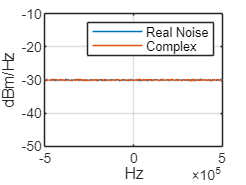

noiseFramesC = reshape(noiseC,fftLen,frames);
noiseFrames = reshape(noise,fftLen,frames);
% Determine PSD in Watts/(Frequency Bin)
noiseFramesFreqC = fft(noiseFramesC,fftLen);
noiseFramesFreq = fft(noiseFrames,fftLen);
% Autocorrelate and calculate mean power
S_kC = mean(abs(noiseFramesFreqC).^2,2)/fftLen;
S_k = mean(abs(noiseFramesFreq).^2,2)/fftLen;
% Convert to dBm/Hz
S_k_DBMHZC = 10*log10(S_kC/bandwidth) + 30;
S_k_DBMHZ = 10*log10(S_k/bandwidth) + 30;
% Plot
freqs = linspace(-bandwidth/2,bandwidth/2,fftLen);
figure;plot(freqs,S_k_DBMHZ,freqs,S_k_DBMHZC);
xlabel('Hz');ylabel('dBm/Hz');grid on;
ylim(noiseFloorDBMHZ+[-20 20]);
legend('Real Noise','Complex');